# Statistical Analysis of Mortality in Germany from 1960 to 2020

## Import death data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 14);

% Specify sheet and range
opts.Sheet = "Germany";
opts.DataRange = "A2:N62";

% Specify column names and types
opts.VariableNames = ["Year", "Total", "January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
myDeath = readtable("/Deaths_in_Germany.xlsx", opts, "UseExcel", false)

myDeath = 61×14 table
    Year      Total        January      February     March    April     May     June     July     August    September    October    November     December 
    ____    __________    _________    __________    _____    _____    _____    _____    _____    ______    _________    _______    ________    __________

    1960    8.7672e+05        85232         99752    85095    69991    69400    63913    64121    62998       60716       70509      69479           75515
    1961     8.503e+05        79924 

clear opts

## Import population size and life expectancy data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:C64";

% Specify column names and types
opts.VariableNames = ["Year", "LifeExpectancy", "PopulationSize"];
opts.VariableTypes = ["double", "double", "double"];

% Import the data
myPop = readtable("/Users/giuliobene3000/Desktop/Programming/MATLAB/Epidemiology/Population and Life Expectancy Germany 1959 - 2021.xlsx", opts, "UseExcel", false)

myPop = 63×3 table
    Year    LifeExpectancy    PopulationSize
    ____    ______________    ______________

    2021        81.57             8.39e+07  
    2020        81.41           8.3784e+07  
    2019        81.26           8.3517e+07  
    2018         81.1           8.3124e+07  
    2017        80.97           8.2658e+07  
    2016        80.84           8.2194e+07  
    2015         80.7           8.1787e+07  
    2014        80.57            8.145e+07  
    2013        80.44           8.1174e+07  
    2012         80.3           8.0973e+07  
    2011        80.16           8.0856e+07  
    2010        80.01           8.0827e+07  
    2009        79.87             8.09e+07  
    2008        79.73           8.1066e+07  
    2007        79.51           8.1278e+07  
    2006        79.29           8.1472e+07  


clear opts

## Store data in a usable format

% Format data on mortality
myDeath = table2array(myDeath);

years = myDeath(:,1);
total_deaths = myDeath(:,2);
myDeath = myDeath(:, 3:end);

% Format data on population size and life expectancy
myPop = table2array(myPop);

myPop = myPop(end:-1:1, :);
lifeExp = myPop(:,2);
popSize = myPop(:,3);

## Plot death seasonality in 2D

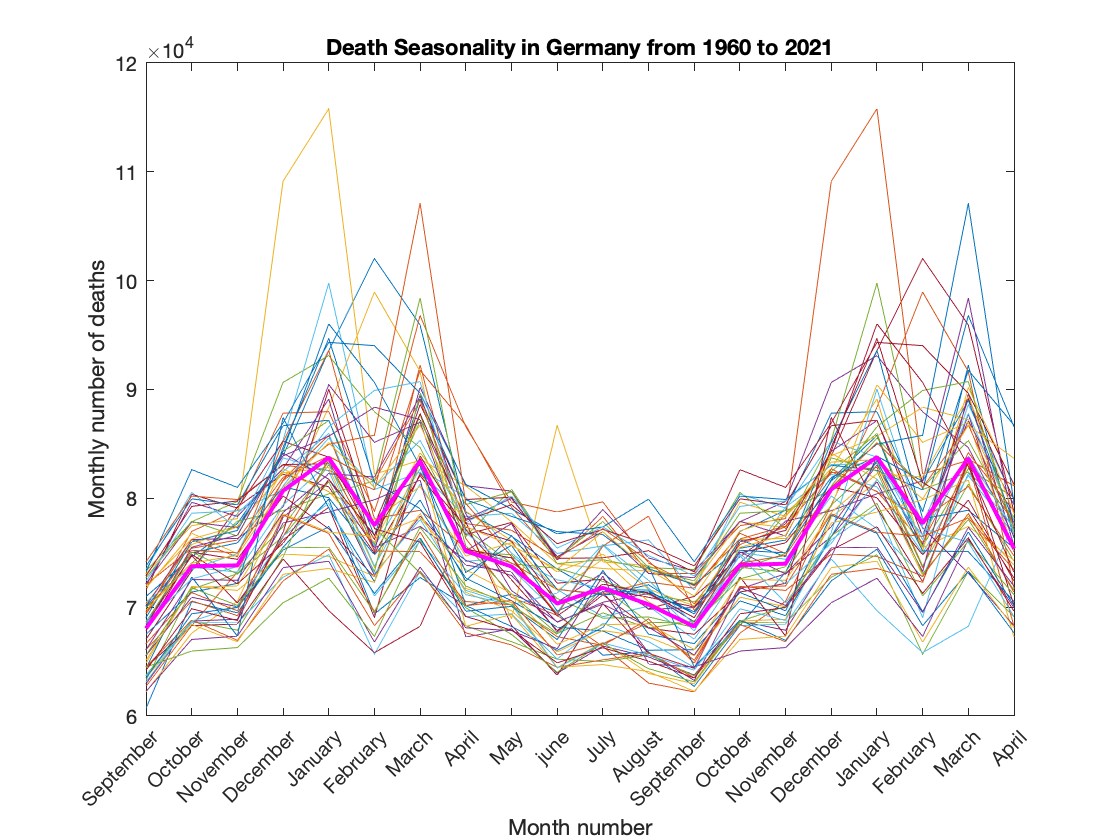

months ={'September', 'October', 'November', 'December', 'January', 'February', 'March', 'April', 'May', 'june', 'July', 'August', 'September', 'October', 'November', 'December', 'January', 'February', 'March', 'April'};

% Iteratively plot mortality vs month
merged_year = zeros(59, 20);

for year = 2:60
    
    last_year = myDeath(year - 1, :);
    current_year = myDeath(year, :);
    next_year = myDeath(year + 1, :);

    merged_year(year - 1, :) = [last_year(end-3:end), current_year, next_year(1:4)];

    plot(1:20, merged_year(year - 1, :))
    hold on

end

% Decorate the plot
plot(1:20, mean(merged_year), 'Color', "m", 'LineWidth', 2, 'LineStyle', "-")

title('Death Seasonality in Germany from 1960 to 2021')

xlabel('Month number')
ylabel('Monthly number of deaths')

xlim([1, 20])
xticks(1:20)

xticklabels(months)
xtickangle(45)
hold off

## Plot death seasonality in 3D

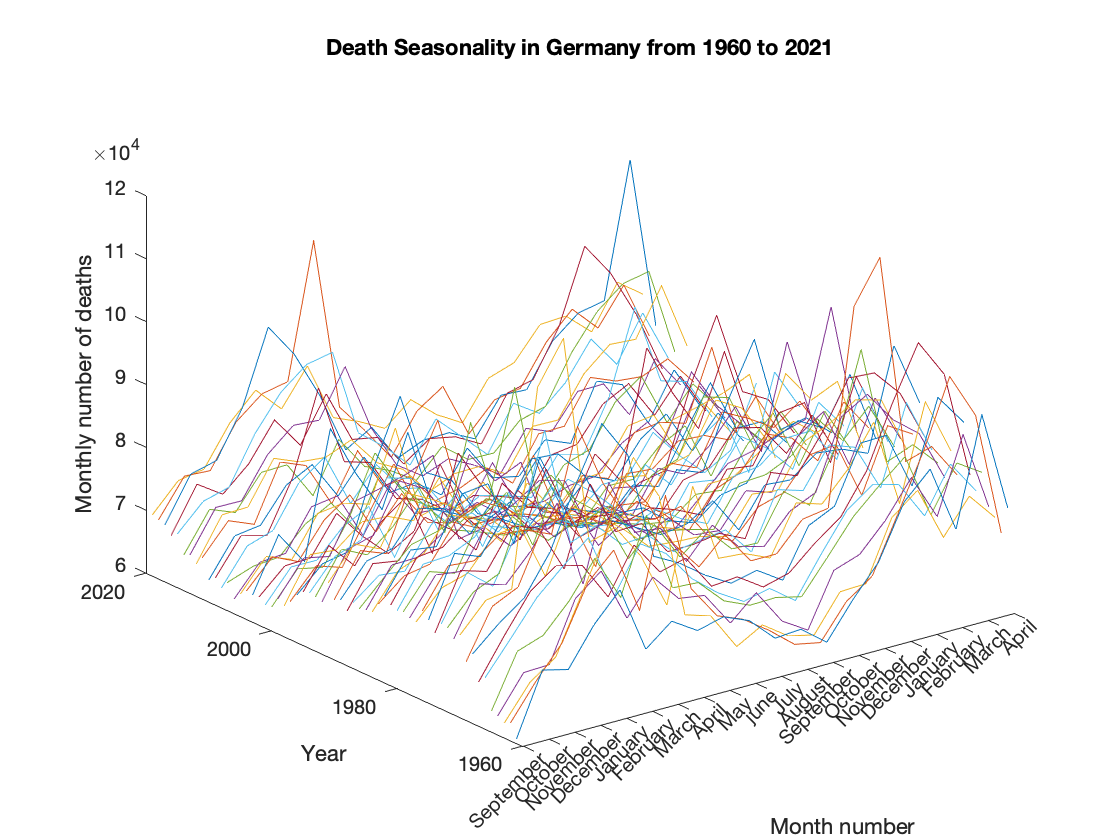

% Iteratively plot mortality vs month and year
for year = 2:60

    plot3(1:20, ones(1,20) * years(year), merged_year(year - 1, :))
    hold on

end

% Decorate the plot
xlabel('Month number')
ylabel('Year')
zlabel('Monthly number of deaths')

title('Death Seasonality in Germany from 1960 to 2021')

xlim([1, 20])
xticks(1:20)

xticklabels(months)
xtickangle(45)
hold off

## Normalise to population size

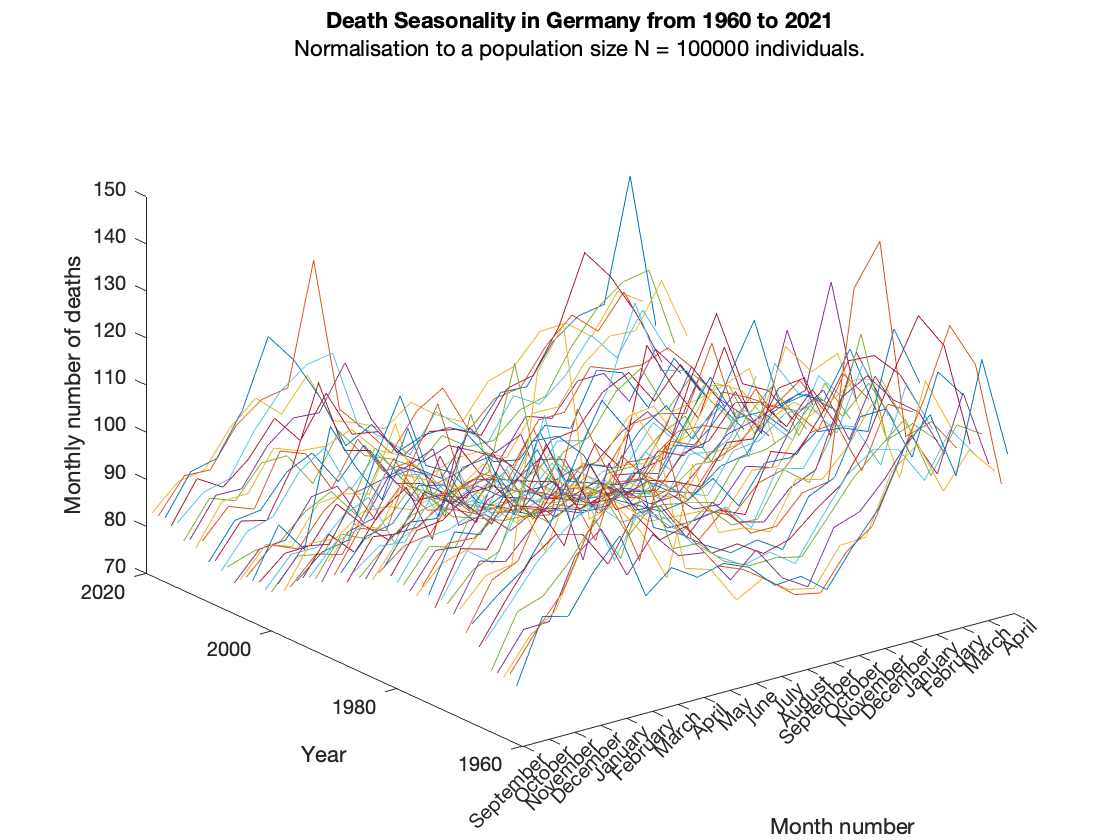

% Normalise to a population N = 100000
mySize = 100000;
norm_merged_year = merged_year ./ popSize(3:end-2) * mySize;

% Iteratively plot mortality vs month and year
for year = 2:60
    
    plot3(1:20, ones(1,20) * years(year), norm_merged_year(year - 1, :))
    hold on

end

% Decorate the plot
xlabel('Month number')
ylabel('Year')
zlabel('Monthly number of deaths')

title('Death Seasonality in Germany from 1960 to 2021')
subtitle(['Normalisation to a population size N = ', num2str(mySize), ' individuals.'])

xlim([1, 20])
xticks(1:20)

xticklabels(months)
xtickangle(45)
hold off